load Scans/r_all.mat
load Scans/theta_all.mat
load Scans/1.7_-0.7scanR.mat
load Scans/1.7_-0.7scanT.mat
load Scans/1.8_-2.8scanR.mat
load Scans/1.8_-2.8scanT.mat
load overhaul_positions.mat

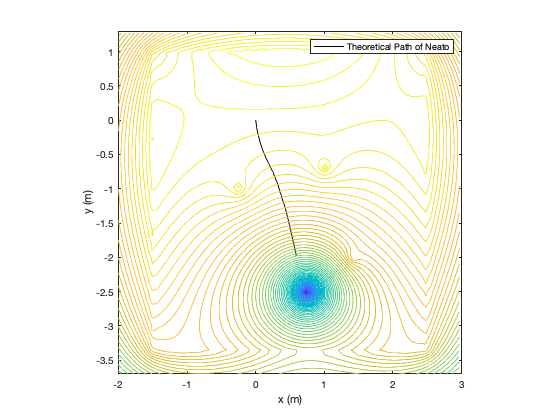

plot(positions(1, :), positions(2, :), "Color", 'k')
xlim([-2 3])
ylim([-3.7 1.3])
hold on
contour(x, y, v, 75)
xlabel('x (m)')
ylabel('y (m)')
axis square
legend(["Theoretical Path of Neato"])
hold off

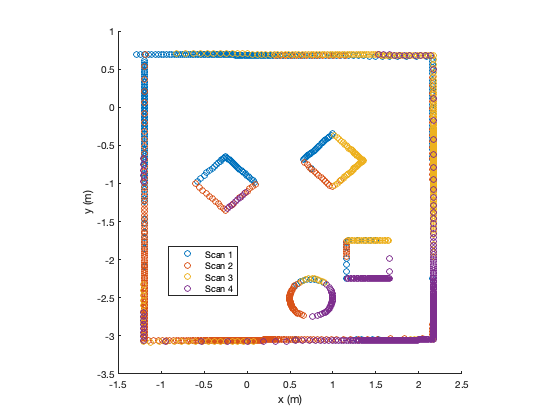

clf;

[x1, y1] = cleancartesian(r_all(:, 1), theta_all(:, 1));

[x2, y2] = cleancartesian(r_all(:, 2), theta_all(:, 2));
[x2, y2] = transformNeatoScan(x2', y2', 0, -2.7);

[x3, y3] = cleancartesian(r_1, theta_1);
[x3, y3] = transformNeatoScan(x3', y3', 1.7, -0.7);

[x4, y4] = cleancartesian(r_2, theta_2);
[x4, y4] = transformNeatoScan(x4', y4', 1.8, -2.8);
scatter(x1, y1)
hold on
scatter(x2, y2)
scatter(x3, y3)
scatter(x4, y4)
xlabel('x (m)')
ylabel('y (m)')
legend('Scan 1', 'Scan 2', 'Scan 3', 'Scan 4', "Location","best")
axis square
hold off

% Load in the encoder data from the Neato's trip 
% and delete any unnecessary data points
% Use this data to get the measured linear velocity, individual wheel 
% velocities, and the angular velocity of the Neato on it's trip
encoder_data = table2array(readtable("encoder_iteration_2.csv"));

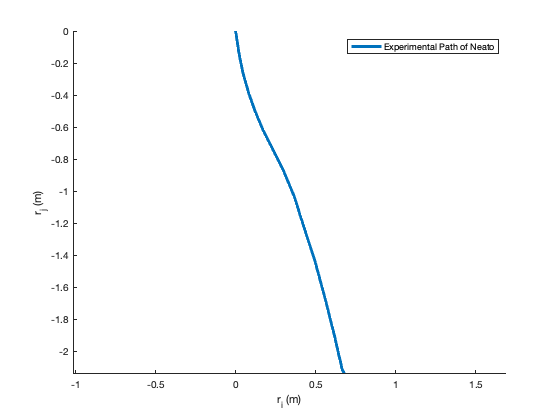


e_time = encoder_data(37:491, 1) - 0.103 - 3.618;
e_L = encoder_data(37:491, 2) + 0.000020448902432690375;
e_R = encoder_data(37:491, 3) + 0.00004810089012607932;
eV_L = diff(e_L)./diff(e_time);
eV_R = diff(e_R)./diff(e_time);
V_e = (eV_L+eV_R)./2;
w_e = (eV_R-eV_L)./0.235;
% Create empty arrays to fill with position values that will be used
% to plot out the measured path
x_e_path = zeros(454, 1);
y_e_path = zeros(454, 1);
theta_e_path = zeros(454, 1);
% Set initial variables and the times
init_T_theta = [1 0];
theta_e_path(1) = atan(init_T_theta(:, 2)/init_T_theta(:, 1));
y_e_path(1) = 0;
x_e_path(1) = 0;
de_time = diff(e_time(2:end));
% Loop through and pull out the position values based on the global
% coordinate system.
for i = 1:453
   y_e_path(i + 1) = y_e_path(i) + V_e(i) * sin(theta_e_path(i)) * de_time(i);
   x_e_path(i + 1) = x_e_path(i) + V_e(i) * cos(theta_e_path(i)) * de_time(i);
   theta_e_path(i+1) = theta_e_path(i) + w_e(i) * de_time(i);
end

% Use the values above to plot the theoretical path of the neato 
clf; hold on; axis equal;

xlabel("r_{i} (m)");
ylabel("r_{j} (m)");
plot(x_e_path, y_e_path, 'lineWidth', 3)
legend("Experimental Path of Neato")
hold off

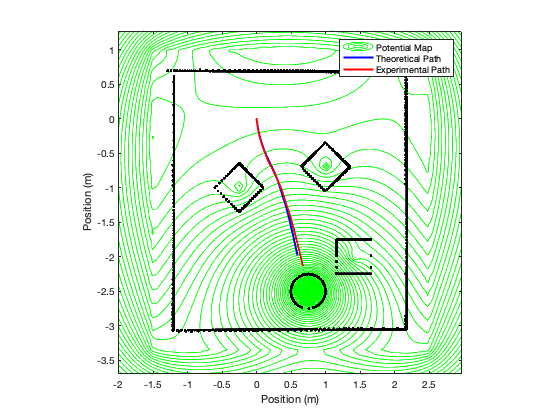

contour(x, y, v, 75, 'g')
hold on
plot(positions(1, :), positions(2, :), 'b', 'LineWidth',2)
plot(x_e_path, y_e_path, 'r', 'LineWidth',2)
scatter(x1, y1, 'k', '.')
scatter(x2, y2, 'k', '.')
scatter(x3, y3, 'k', '.')
scatter(x4, y4, 'k', '.')
legend(["Potential Map","Theoretical Path","Experimental Path"])
xlabel("Position (m)")
ylabel("Position (m)")
axis square
hold off

% Take the mean of the final encoder data points from the neato
% to get the distance travelled.
distanceTravelled = mean([2.3745 2.1430])

Distance = 2.2588